# Open-loop behaviour of state space models in MATLAB

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours and analysis. A common linear model type is the state space model. 

This file focuses on how we can infer the expected open-loop behaviour of a state space models, both continuous and discrete. There are significant overlaps with the transfer function based files in the toolbox (***transferfunctions_and_behaviours, step_responses_with_matlab***) and so the reader may like to look at those in parallel. It is also worth being familiar with the preceding files of`: `***statespace_models_from_tf_control101, tf_models_from_statespace_control101***.

Specifically here we show how to expose the core dynamics and remind the user how to make use of ***step.m. ***A discussion of phase diagrams comes in the resource:*** phase_plane_statespace_control101.***

Lots of code snippets are provided as examples of how MATLAB can be used and the intention is that readers can use these as exemplars and/or templates and change the models and scenarios for their own need.

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, Ross Drummond, Lanlan Su (University of Sheffield) and Ruth Bars ( Budapest University of Technology and Economics)                           

## Table of Contents

- Background on finding transfer functions from state space models

- Core observation on behaviours

- Step responses with MATLAB

## 1. Background on finding transfer function models from state space models

The earlier file ***tf_models_from_statespace_control101 ***showed how to find a transfer function model from a state space model. This resource will take that background as read.

$\dot{X} =A\;X+B\;U;\;Y=C\;X+D\;U,\;$with state *X*, input *U* and output *Y*. 

Take Laplace transforms of every element in this model, thus:


$$X\left(s\right)={\left\lbrack s\;I-A\right\rbrack }^{-1} B\;U\left(s\right);\;\;\;Y\left(s\right)=\underset{G\left(s\right)}{\underbrace{\left(C{\left\lbrack s\;I-A\right\rbrack }^{-1} B+D\right)} \;} U\left(s\right)=G\left(s\right)U\left(s\right)$$


## 2 Core observation on behaviours

From this it will be clear that the transfer function equivalent has a denominator given by:


$$d\left(s\right)=\det \left(s\;I-A\right)$$


Readers will also be familiar with the fact that one can solve for the eigenvalues of a matrix using the formula


$$\det \left(\lambda I-A\right)=0$$


from which it is evident that the roots of *d(s)*, that is the poles, correspond to the eigenvalues of *A*.

**Remark:** Links between pole positions and ouput behaviour is explored in the file: ***transferfunctions_and_behaviours ***and thus is not repeated here.

One can validate this with some simple MATLAB commands comparing the eigenvalues with the poles.

disp('Section 2 below')
A=[-0.8 0.1;0.2 -0.5];B=[1 3;2 0];C=[1 0;1 -1];D=[0 0; 0 0];
G=ss(A,B,C,D);
poles = pzmap(G)

poles =    -0.8562
   -0.4438


eigenvalues  = eig(A)

eigenvalues =    -0.8562
   -0.4438


End of section 2


## 3. Step responses with MATLAB

This section is deliberately concise as it largely replicates the file: ***step_responses_with_matlab ***

In simple terms, once one has defined a linear system object, whether this is transfer function based, state space or indeed continuous or discrete, the MATLAB call statement is essentially the same as MATLAB determines the object type behind the scenes and then does the computations required. It also determines the system dimension and produces IO data for every input-ouput pairing.

### 3.1 Basic operation of step.m 

The simplest use of ***step.m*** is to allow MATLAB to take all the decisions, such as, for how long is the step response wanted, how many points shall I calculate the response at and so forth; to do this simply provide the model as shown below. This option produces a figure.  Change lines below to explore different systems.

disp('BELOW is SECTION 3.1')

BELOW is SECTION 3.1


A=[-1 -3;-1.2 -5];
B=[2;-1];
C=[1 1];
D=0;
G=ss(A,B,C,D);

G =
 
  A = 
         x1    x2
   x1    -1    -3
   x2  -1.2    -5
 
  B = 
       u1
   x1   2
   x2  -1
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Properties


poles_of_A=eig(A)

poles_of_A =    -0.2432
   -5.7568


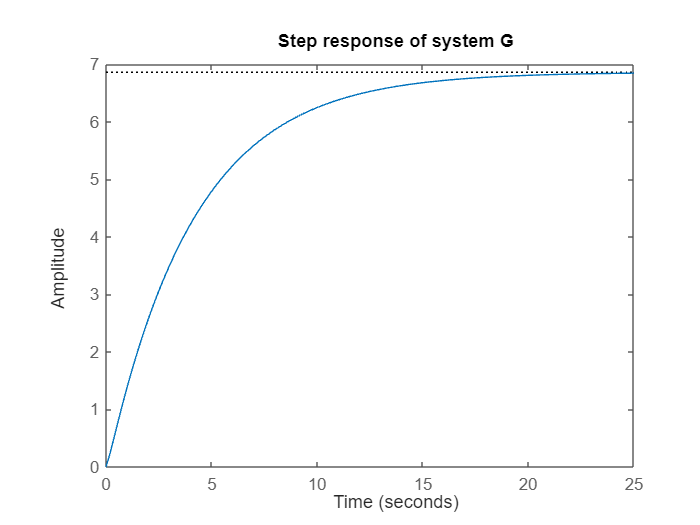

step(G)
title('Step response of system G')

### 3.2 Controlling the end time of the figure 

Should you want to insist on the time scale used for the step response, simply add a second input argument as a scalar, which is the end time.

disp('BELOW is SECTION 3.2')

BELOW is SECTION 3.2


endtimeG = 20

endtimeG = 20

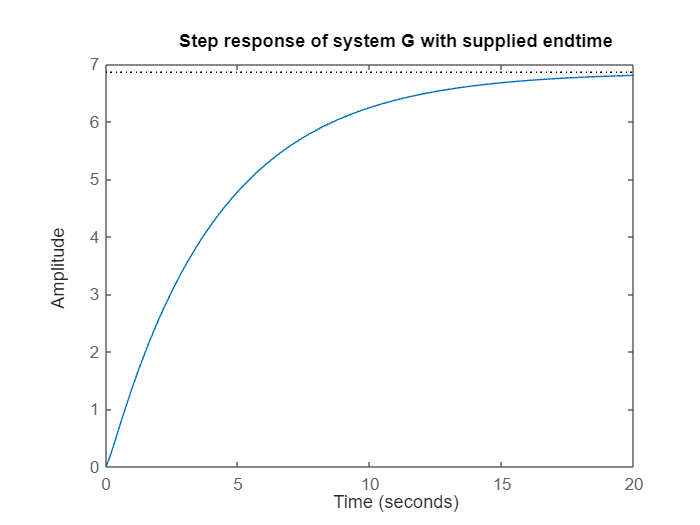

step(G,endtimeG)
title('Step response of system G with supplied endtime')

### 3.3 Collecting the numerical values of the step response

It may be that you want the numerical values of the step response. Typical code is shown here.

disp('BELOW is SECTION 3.3')

BELOW is SECTION 3.3


endtimeG = 1.2;
[yvaluesg, ytimesg] = step(G,endtimeG)

yvaluesg =          0
    0.0123
    0.0250
    0.0382
    0.0518
    0.0657
    0.0800
    0.0947
    0.1096
    0.1248


ytimesg =          0
    0.0120
    0.0240
    0.0360
    0.0480
    0.0600
    0.0720
    0.0840
    0.0960
    0.1080


#### 3.4 Output step response for a MIMO discrete system

Define the model to be discrete and otherwise the call statements are essentially the same. In this case using a MIMO case and it is seen that MATLAB produces separate subplots for each input/output pairing.

disp('Section 3.4 below')

Section 3.4 below


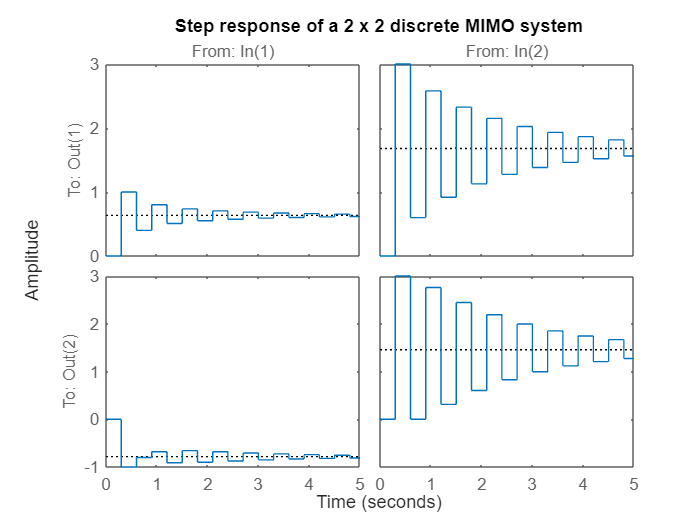

A=[-0.8 0.1;0.2 -0.5];B=[1 3;2 0];C=[1 0;1 -1];D=[0 0; 0 0]; Tsamp=0.3;
G=ss(A,B,C,D,Tsamp);  % sample time set as Tsamp
step(G,5)
title('Step response of a 2 x 2 discrete MIMO system')

### 3.5 Overlaying responses and more

To avoid repetition, the reader is referred to the transfer function based file ***step_responses_with_matlab ***for more information on how to use ***step.m*** and create nice plots for reports.